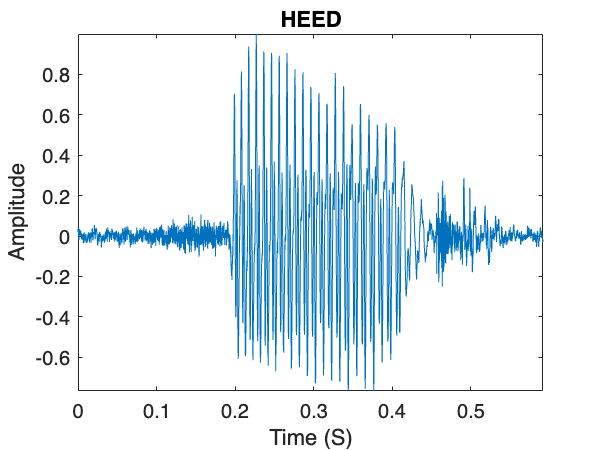

% FEATURE EXTRACTION // FEATURE EXTRACTION // FEATURE EXTRACTION // FEATURE EXTRACTION
% Shared folder

%Note switch these audios to analyse different signals
% one as the training set and another as the test set
[heed, fs_heed] = audioread('sp01a_w01_heed.mp3'); 
[hid, fs_hid]  = audioread('sp01a_w02_hid.mp3');
[head, fs_head]  = audioread('sp01a_w03_head.mp3');
[had, fs_had]  = audioread('sp01a_w04_had.mp3');
[hard, fs_hard]  = audioread('sp01a_w05_hard.mp3');
[hud, fs_hud]  = audioread('sp01a_w06_hud.mp3');
[hod, fs_hod]  = audioread('sp01a_w07_hod.mp3');
[hoard, fs_hoard]  = audioread('sp01a_w08_hoard.mp3');
[hood, fs_hood]  = audioread('sp01a_w09_hood.mp3');
[whod, fs_whod]  = audioread('sp01a_w10_whod.mp3');
[heard, fs_heard]  = audioread('sp01a_w11_heard.mp3');

t1 = (0:length(heed)-1) / fs_heed; 
t2 = (0:length(hid)-1) / fs_hid;  
t3 = (0:length(head)-1) / fs_head; 
t4 = (0:length(had)-1) / fs_had;
t5 = (0:length(hard)-1) / fs_hard; 
t6 = (0:length(hud)-1) / fs_hud;
t7 = (0:length(hod)-1) / fs_hod; 
t8 = (0:length(hoard)-1) / fs_hoard;
t9 = (0:length(hood)-1) / fs_hood; 
t10 = (0:length(whod)-1) / fs_whod;
t11 = (0:length(heard)-1) / fs_heard; 


% PLOT OF SIGNALS
plot(t1, heed);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HEED');

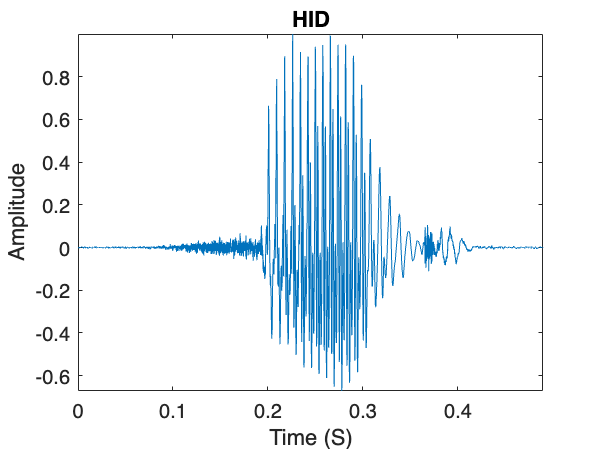


plot(t2, hid);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HID');

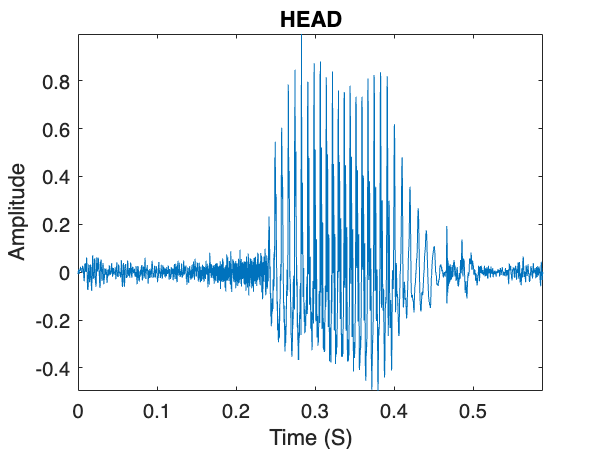


plot(t3, head);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HEAD');

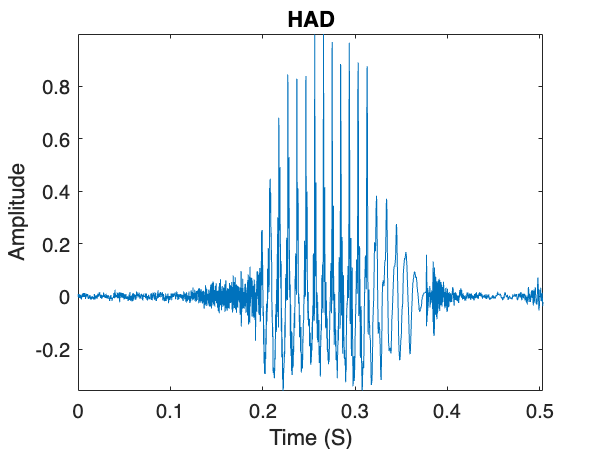


plot(t4, had);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HAD');

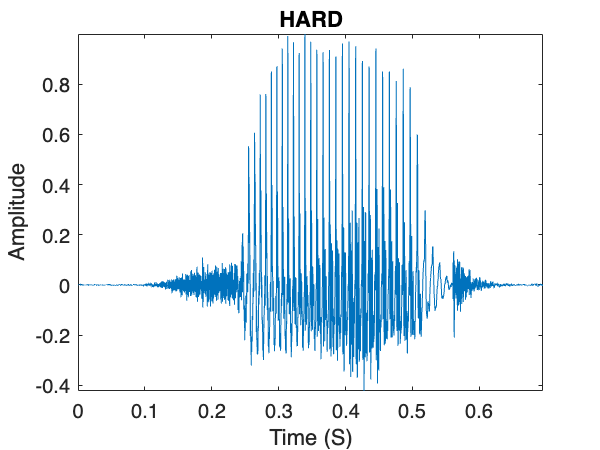

 
plot(t5, hard);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HARD');

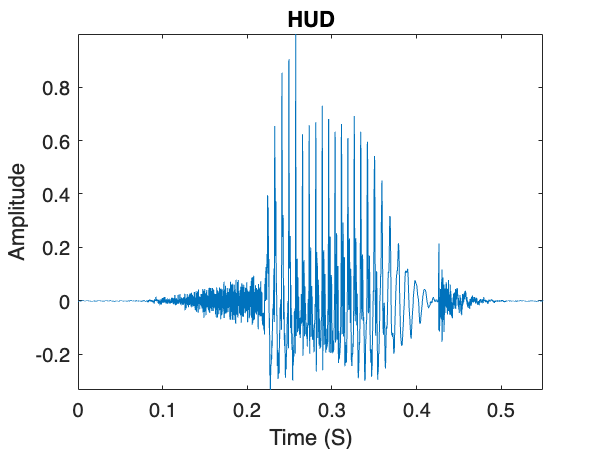


plot(t6, hud);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HUD');

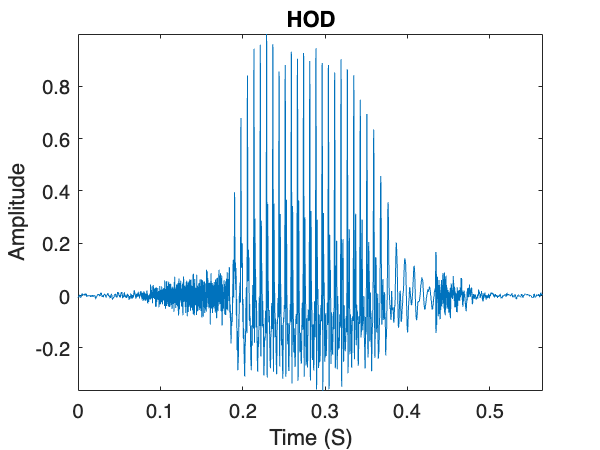


plot(t7, hod);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HOD');

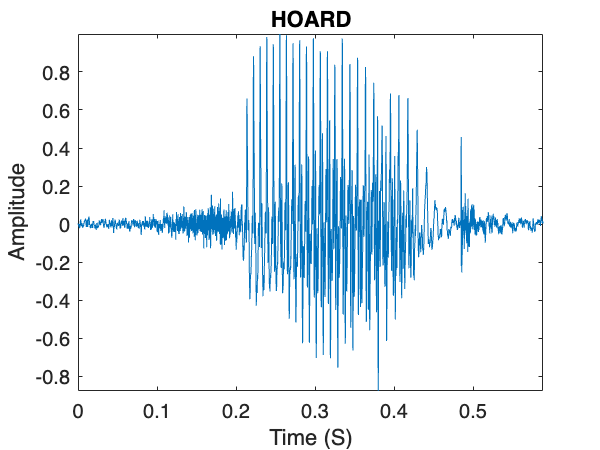


plot(t8, hoard);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HOARD');

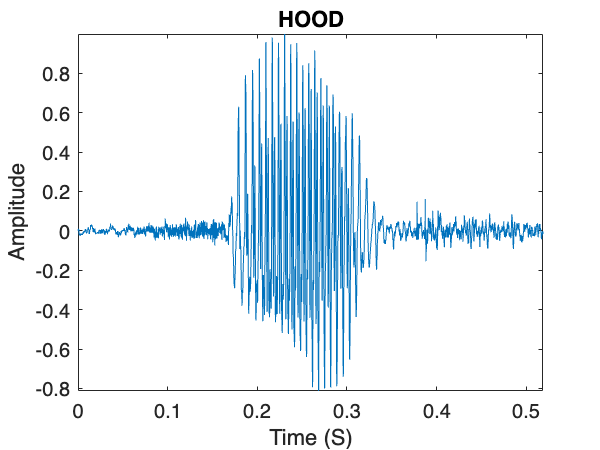


plot(t9, hood);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HOOD');

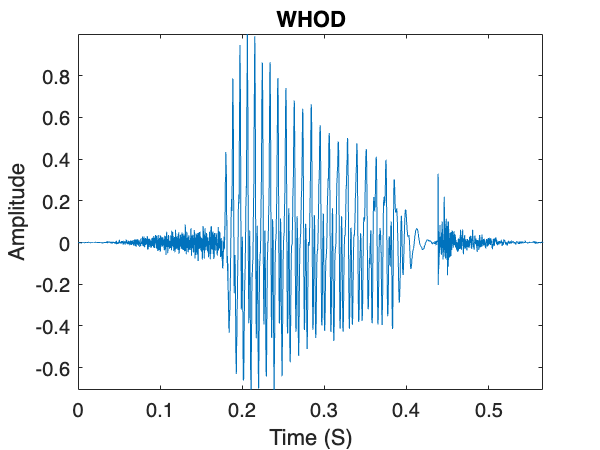


plot(t10, whod);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('WHOD');

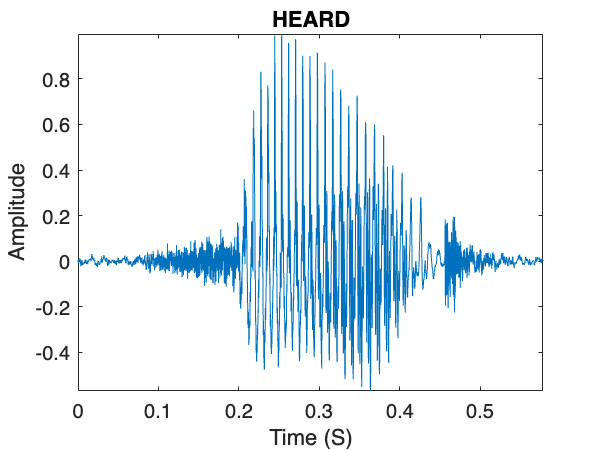


plot(t11, heard);  
axis tight
xlabel('Time (S)');
ylabel('Amplitude');
title('HEARD');




% PARAMETERS
frame_length_ms = 30;   % Frame length in ms
hop_size_ms = 10;       % Hop size in ms
num_mfcc_coeffs = 13;   % Number of MFCC coefficients (including zeroth)

% Frame size and hop size in samples
frame_length_samples = round(frame_length_ms / 1000 * fs_heed);  % Convert ms to samples
hop_size_samples = round(hop_size_ms / 1000 * fs_heed);        % Convert ms to samples

% Define a function for extracting MFCCs from a windowed frame
extract_mfcc_from_frame = @(audio, fs, frame_length, hop_size, num_coeffs) ...
    mfcc(audio, fs, 'Window', hamming(frame_length, 'periodic'), ...
         'OverlapLength', frame_length - hop_size, 'NumCoeffs', num_coeffs);


% Extract MFCCs for each audio file using frame-based processing
mfcc_heed = extract_mfcc_from_frame(heed, fs_heed, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hid = extract_mfcc_from_frame(hid, fs_hid, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_head = extract_mfcc_from_frame(head, fs_head, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_had = extract_mfcc_from_frame(had, fs_had, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hard = extract_mfcc_from_frame(hard, fs_hard, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hud = extract_mfcc_from_frame(hud, fs_hud, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hod = extract_mfcc_from_frame(hod, fs_hod, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hoard = extract_mfcc_from_frame(hoard, fs_hoard, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_hood = extract_mfcc_from_frame(hood, fs_hood, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_whod = extract_mfcc_from_frame(whod, fs_whod, frame_length_samples, hop_size_samples, num_mfcc_coeffs);
mfcc_heard = extract_mfcc_from_frame(heard, fs_heard, frame_length_samples, hop_size_samples, num_mfcc_coeffs);

% DISPLAY THE MFCCs
disp('MFCC for "heed":');

MFCC for "heed":


disp(mfcc_heed);

   -1.7754  -14.6974    1.9237    0.3500    0.2304    0.0901    0.1254   -0.3241    0.0665   -0.0588    0.2048    0.0202   -0.1385    0.0638
   -1.7015  -14.8055    2.3536    0.6853    0.4815    0.1497    0.2162   -0.2748    0.0782   -0.1835    0.4160    0.0841    0.0256    0.0624
   -1.7541  -14.5638    2.1142    0.5267    0.2646   -0.0174   -0.2225   -0.2598    0.0768   -0.2105    0.2365    0.3285   -0.0454   -0.1334
   -1.8085  -14.5093    1.6506    0.5101    0.3607    0.0005   -0.1521   -0.3458    0.0146    0.3316    0.0758    0.0850   -0.2612   -0.3511
   -1.6115  -14.1266    1.8473    0.5639    0.3966    0.0024   -0.0710   -0.4745   -0.0937    0.0240   -0.1258   -0.1760   -0.1624   -0.0584
   -1.5624  -13.9797    1.9592    0.4540    0.2477    0.0335    0.0435   -0.2813   -0.2347   -0.0787    0.0346   -0.1115    0.1538    0.2226
   -1.7197  -14.1183    1.5722    0.2038    0.4712   -0.3074   -0.2560   -0.0348    0.1882    0.1080    0.1624    0.0329   -0.1059    0.0344
   -1.7988  -


disp('MFCC for "hid":');

MFCC for "hid":


disp(mfcc_hid);

   -6.3157  -20.5038    2.0567    0.4435    0.0652    0.1385    0.2228    0.0768    0.3056   -0.0270   -0.0660    0.0312   -0.0919   -0.0688
   -6.4120  -20.5120    1.5771    0.0161   -0.1488   -0.2676    0.0272    0.1341    0.0739   -0.2327   -0.3166   -0.0985   -0.0825   -0.1769
   -6.3360  -20.1035    1.9889    0.3642    0.0171   -0.0703    0.1493   -0.1225   -0.1141    0.1761   -0.0288   -0.1074   -0.1287   -0.0403
   -6.1271  -19.9501    2.0782    0.7410    0.0778   -0.3798    0.0628   -0.0347   -0.2073    0.1907    0.0001   -0.1127   -0.0770    0.0496
   -6.1612  -19.8671    1.5621    0.4020    0.1603   -0.0744   -0.3643    0.0639    0.0905    0.0159   -0.0041   -0.1030   -0.2403   -0.0262
   -5.8756  -19.6399    1.0153    0.4732    0.2423    0.2799   -0.1094   -0.0681    0.2615    0.2542    0.0376   -0.1690   -0.1147   -0.0213
   -5.5070  -18.9358    1.5147    0.2630    0.1719    0.1072    0.1480   -0.2676    0.0419    0.2525    0.0583   -0.2533   -0.1451    0.3735
   -4.9376  -


disp('MFCC for "head":');

MFCC for "head":


disp(mfcc_heed);

   -1.7754  -14.6974    1.9237    0.3500    0.2304    0.0901    0.1254   -0.3241    0.0665   -0.0588    0.2048    0.0202   -0.1385    0.0638
   -1.7015  -14.8055    2.3536    0.6853    0.4815    0.1497    0.2162   -0.2748    0.0782   -0.1835    0.4160    0.0841    0.0256    0.0624
   -1.7541  -14.5638    2.1142    0.5267    0.2646   -0.0174   -0.2225   -0.2598    0.0768   -0.2105    0.2365    0.3285   -0.0454   -0.1334
   -1.8085  -14.5093    1.6506    0.5101    0.3607    0.0005   -0.1521   -0.3458    0.0146    0.3316    0.0758    0.0850   -0.2612   -0.3511
   -1.6115  -14.1266    1.8473    0.5639    0.3966    0.0024   -0.0710   -0.4745   -0.0937    0.0240   -0.1258   -0.1760   -0.1624   -0.0584
   -1.5624  -13.9797    1.9592    0.4540    0.2477    0.0335    0.0435   -0.2813   -0.2347   -0.0787    0.0346   -0.1115    0.1538    0.2226
   -1.7197  -14.1183    1.5722    0.2038    0.4712   -0.3074   -0.2560   -0.0348    0.1882    0.1080    0.1624    0.0329   -0.1059    0.0344
   -1.7988  -


disp('MFCC for "hid":');

MFCC for "hid":


disp(mfcc_hid);

   -6.3157  -20.5038    2.0567    0.4435    0.0652    0.1385    0.2228    0.0768    0.3056   -0.0270   -0.0660    0.0312   -0.0919   -0.0688
   -6.4120  -20.5120    1.5771    0.0161   -0.1488   -0.2676    0.0272    0.1341    0.0739   -0.2327   -0.3166   -0.0985   -0.0825   -0.1769
   -6.3360  -20.1035    1.9889    0.3642    0.0171   -0.0703    0.1493   -0.1225   -0.1141    0.1761   -0.0288   -0.1074   -0.1287   -0.0403
   -6.1271  -19.9501    2.0782    0.7410    0.0778   -0.3798    0.0628   -0.0347   -0.2073    0.1907    0.0001   -0.1127   -0.0770    0.0496
   -6.1612  -19.8671    1.5621    0.4020    0.1603   -0.0744   -0.3643    0.0639    0.0905    0.0159   -0.0041   -0.1030   -0.2403   -0.0262
   -5.8756  -19.6399    1.0153    0.4732    0.2423    0.2799   -0.1094   -0.0681    0.2615    0.2542    0.0376   -0.1690   -0.1147   -0.0213
   -5.5070  -18.9358    1.5147    0.2630    0.1719    0.1072    0.1480   -0.2676    0.0419    0.2525    0.0583   -0.2533   -0.1451    0.3735
   -4.9376  -


disp('MFCC for "hard":');

MFCC for "hard":


disp(mfcc_hard);

   -7.2842  -22.6012    2.2527    0.6246    0.5804    0.0018   -0.3515   -0.2554    0.2206    0.0572   -0.6345    0.2216    0.1231   -0.2793
   -7.3711  -22.1332    2.0079    0.8168    0.7212    0.2762   -0.1919   -0.1809    0.1876    0.2879   -0.2776    0.0541    0.1196   -0.0917
   -7.1271  -22.5857    1.7757    1.0990    0.9141    0.1518   -0.4793   -0.4445    0.1197    0.1679   -0.0103   -0.0728    0.0672   -0.0688
   -7.1691  -22.1781    1.8397    0.8961    0.7974    0.3259   -0.5487   -0.4412    0.0458   -0.1133   -0.0940    0.1021   -0.1600   -0.0836
   -6.9465  -22.0887    1.5324    0.8304    0.7993    0.2969   -0.2852   -0.3925    0.1587    0.4337    0.1224    0.2351   -0.0333   -0.0503
   -6.9173  -22.1892    1.3965    1.0327    1.2306    0.3555   -0.2381   -0.1898    0.3364    0.4133    0.0646    0.2097    0.1532   -0.0028
   -6.8280  -21.8722    1.3311    1.0415    1.1279    0.3068   -0.3003   -0.4173    0.2168    0.2893    0.0350    0.0968    0.2158    0.2060
   -6.8171  -


disp('MFCC for "hud":');

MFCC for "hud":


disp(mfcc_hud);

   -8.2551  -23.1225    1.4353    0.5453    0.4866    0.1089   -0.0532    0.0907    0.2465    0.1225   -0.0956    0.1333    0.0504    0.0030
   -7.9534  -23.0820    1.1752    0.1691    0.4275    0.0141   -0.1781    0.0042    0.1854   -0.1008   -0.0496    0.0094    0.0414   -0.1386
   -7.9581  -23.0003    1.4167    0.7043    0.4409    0.2160    0.0459    0.0001    0.1999    0.1395   -0.1673   -0.1481    0.0697    0.5338
   -8.0294  -22.8359    1.2641    0.5445    0.4781    0.2736    0.1640   -0.0466    0.1321    0.0184   -0.3277   -0.0921    0.0522    0.4005
   -8.1396  -23.2245    0.6578    0.3121    0.3299   -0.0250    0.1573    0.1803    0.2383    0.0741   -0.0090    0.2030    0.3788    0.1391
   -8.0424  -22.7869    0.7544    0.3882    0.2402   -0.1780   -0.0046    0.1131    0.3373    0.2451   -0.0629    0.0765    0.4027    0.1509
   -6.4105  -21.2413    0.9900    0.0978    0.3310   -0.0356   -0.1200   -0.0972    0.0652    0.1532   -0.0777    0.1686    0.4388    0.0776
   -5.1081  -


disp('MFCC for "hod":');

MFCC for "hod":


disp(mfcc_hod);

   -4.6552  -20.9368    2.6628    0.9890    0.8173    0.2045   -0.0757   -0.4093    0.1082    0.0018   -0.3548    0.0156    0.1939    0.3162
   -4.6208  -20.6934    2.5634    0.9934    1.0594    0.5111    0.0882   -0.3383    0.2870    0.1350   -0.2364   -0.0425    0.2218    0.3905
   -4.0211  -20.3719    2.3379    1.0071    1.0496    0.5628    0.0756   -0.1763    0.1858    0.1654   -0.2132   -0.1091    0.0772    0.2765
   -3.9893  -19.3550    2.2894    0.9517    1.0679    0.3750   -0.0166   -0.1520    0.2118    0.3270   -0.0653    0.1758    0.1712    0.0363
   -3.7136  -18.3555    1.7342    0.6923    1.0200    0.3175   -0.2038   -0.2426    0.2534    0.3779    0.2439    0.2167    0.1974    0.1434
   -3.7688  -17.5457    1.6418   -0.0355    0.6162    0.4419    0.2644   -0.2579    0.2366    0.5024    0.1723    0.1202    0.0940    0.1283
   -3.2536  -16.5306    1.8415   -0.2816    0.5410    0.0631    0.2378   -0.5545    0.0246    0.4382    0.3484   -0.0140   -0.1122    0.1196
   -2.5267  -


disp('MFCC for "hoard":');

MFCC for "hoard":


disp(mfcc_hoard);

   -2.2952  -16.8205    3.3777    0.3086    0.7405    0.3964    0.3241   -0.0662   -0.0508    0.0855   -0.3246   -0.2683    0.3837    0.1499
   -2.2273  -17.0670    3.2286    0.0762    0.6114    0.2454    0.1418   -0.0204    0.1344   -0.1112   -0.1552   -0.2807    0.3713    0.3288
   -2.1989  -17.0741    3.1494    0.5739    0.9103    0.3280   -0.0577    0.2030    0.1169   -0.0325   -0.1406    0.0003    0.4444    0.1008
   -2.2581  -16.6129    3.3129    0.7273    0.8700    0.2702   -0.1609   -0.4450   -0.1472    0.2575    0.0287   -0.1663    0.1849   -0.0775
   -2.0996  -16.3964    2.7844    0.5852    1.0222    0.3282   -0.1474   -0.3401   -0.2932    0.0456    0.0550   -0.0375    0.2776   -0.0013
   -2.1281  -16.0676    2.5172    0.7390    0.6657    0.1820   -0.1697   -0.2348   -0.1449    0.0928   -0.1554    0.1008    0.4210    0.1102
   -2.0154  -15.8259    2.7121    0.4440    0.4843    0.0957    0.1296   -0.0740    0.3551    0.3030   -0.3953   -0.3232    0.1098    0.0183
   -2.0689  -


disp('MFCC for "hood":');

MFCC for "hood":


disp(mfcc_hood);

   -2.5830  -17.5212    3.1102    0.2200    0.7177    0.1454    0.0190   -0.1727    0.3768    0.3401   -0.0667    0.2315    0.1068   -0.3589
   -2.5491  -17.6117    3.0128    0.0001    0.2102   -0.0453   -0.2506   -0.2900    0.1887    0.2913   -0.1752   -0.0071    0.1642   -0.1885
   -2.6338  -17.3711    2.8110    0.1525    0.1541    0.1468    0.0828   -0.0619    0.1391    0.1168   -0.2020   -0.2403    0.0228   -0.1680
   -2.4133  -17.3764    2.9182    0.0132    0.1556   -0.0350   -0.0541   -0.4199   -0.2907    0.0872    0.0169   -0.0860    0.0674    0.1075
   -2.4609  -16.8364    2.8331   -0.0581    0.7030    0.2754    0.1160   -0.3332   -0.2265   -0.0296    0.0365   -0.5179   -0.1584    0.2292
   -2.4776  -16.2607    2.2940   -0.2055    1.0166    0.3921   -0.0308   -0.4984    0.0960    0.1706    0.1652   -0.1653   -0.0698    0.4559
   -2.2890  -15.4968    2.1037   -0.5206    0.5377    0.1296    0.4131   -0.2364    0.0680    0.2044    0.4556    0.0637   -0.1030    0.0658
   -2.0366  -


disp('MFCC for "whod":');

MFCC for "whod":


disp(mfcc_whod);

   -7.0073  -21.6749    0.4825    0.6732    0.2811    0.1006   -0.0814   -0.1972    0.0007   -0.1389    0.1419   -0.1255   -0.0353    0.0374
   -6.8135  -21.3624    0.0976    0.4102    0.2172    0.0560   -0.1380   -0.0757    0.1682    0.0553    0.0757   -0.1326   -0.0517   -0.0681
   -6.0858  -20.2339    0.0829    0.3355    0.3536    0.3247   -0.2516   -0.0846    0.0940    0.0129   -0.0984    0.0250    0.1665    0.1134
   -5.2841  -18.6453    0.6650    0.3917    0.0593    0.1305   -0.4128    0.1751    0.4362    0.2310    0.2175    0.0389    0.2347    0.2934
   -4.5018  -17.4792    1.2562    0.0675   -0.0042    0.4233   -0.0648   -0.0804    0.2025    0.3094    0.0368   -0.1108   -0.0957   -0.0344
   -3.7830  -16.5713    1.6737   -0.2016    0.0951   -0.0646   -0.1824   -0.3242   -0.0056    0.1399    0.1316   -0.3322   -0.2017    0.1199
   -3.0469  -15.6536    1.7446   -0.5583    0.0797   -0.0945   -0.2984   -0.3445    0.1895    0.1322    0.0184   -0.2652   -0.0659    0.3665
   -2.4481  -


disp('MFCC for "heard":');

MFCC for "heard":


disp(mfcc_heard);

   -2.8156  -18.4951    3.1185    0.2486    0.5394    0.2531   -0.3021   -0.0846   -0.0070   -0.1319    0.1388    0.1099   -0.1403   -0.2192
   -2.7173  -18.4392    3.1382    0.5214    0.6433    0.2103   -0.3126    0.0982   -0.2016    0.2063    0.3794    0.2949    0.1099   -0.1852
   -2.9654  -18.0371    3.2508    0.2946    0.1661    0.0753   -0.1937   -0.0912   -0.2586    0.2865   -0.0399   -0.1403   -0.0123    0.1070
   -3.1745  -18.3260    3.0605    0.2192    0.3089   -0.0103   -0.2180   -0.2320   -0.0217    0.2589   -0.0458    0.0248    0.3324    0.2616
   -3.1476  -18.1255    2.8157    0.6533    0.5295    0.2275   -0.1687   -0.0737    0.1056    0.0160   -0.3401    0.0141    0.3198    0.1284
   -2.8523  -17.2926    2.1967    0.6780    0.8697    0.0339   -0.3612    0.0552    0.0694    0.1847   -0.0923   -0.0156    0.2021   -0.0855
   -2.1940  -16.2901    1.6567    0.5716    1.2183    0.1461   -0.3245   -0.2223   -0.0633    0.0838    0.0985    0.2311    0.1408    0.0098
   -1.8995  -

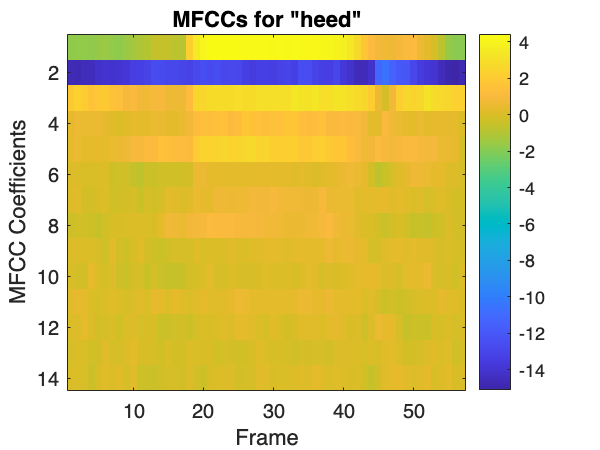



% DISPLAY OF THE MFCC OF THE AUDIO SIGNALS - SPECTOGRAM
imagesc(mfcc_heed');  % Transpose to display the frames on the x-axis
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "heed"');

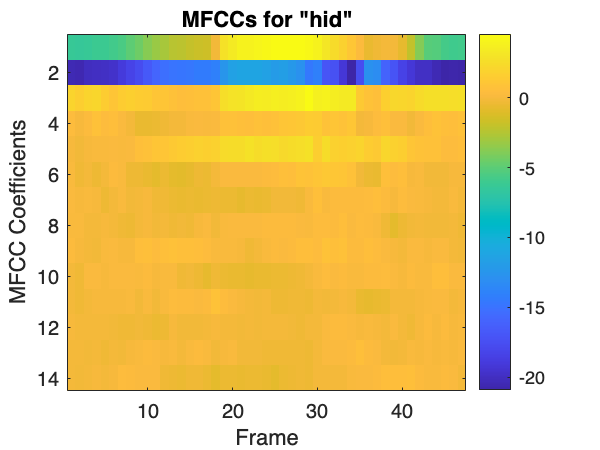


imagesc(mfcc_hid');  
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hid"');

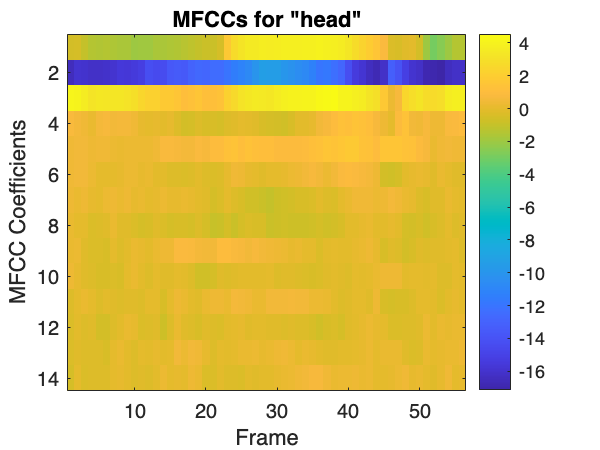


imagesc(mfcc_head');  
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "head"');

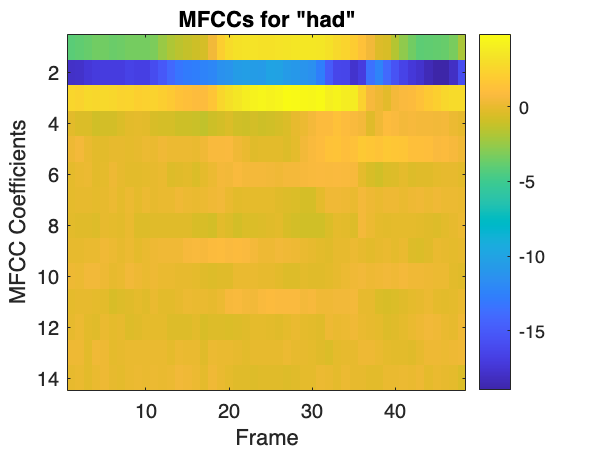


imagesc(mfcc_had'); 
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "had"');

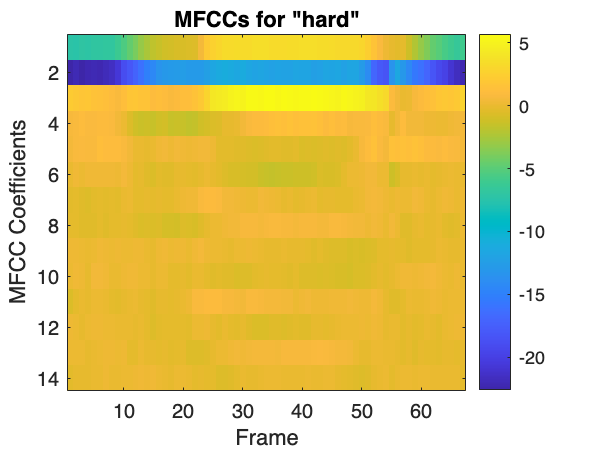


imagesc(mfcc_hard'); 
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hard"');

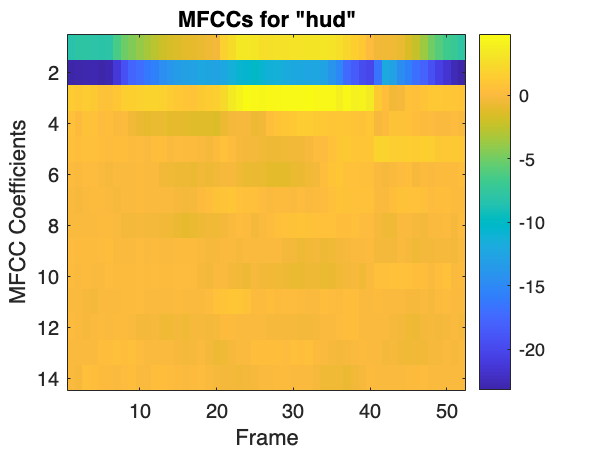


imagesc(mfcc_hud'); 
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hud"');

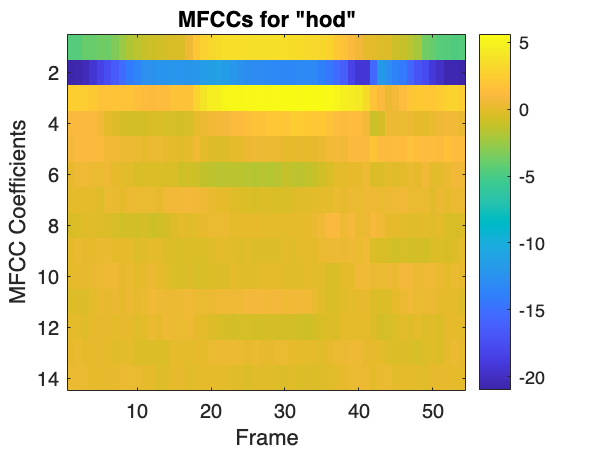


imagesc(mfcc_hod'); 
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hod"');

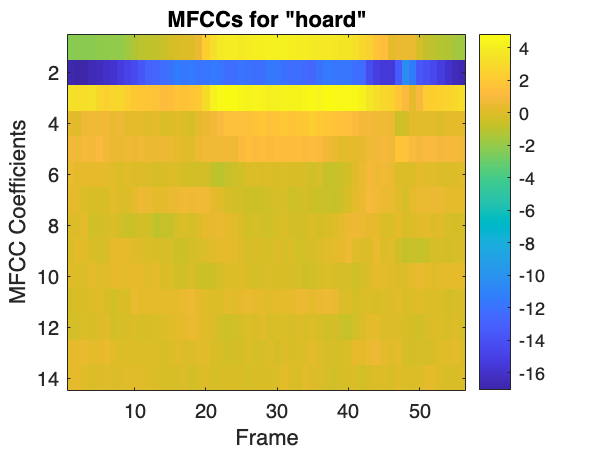


imagesc(mfcc_hoard');  
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hoard"');

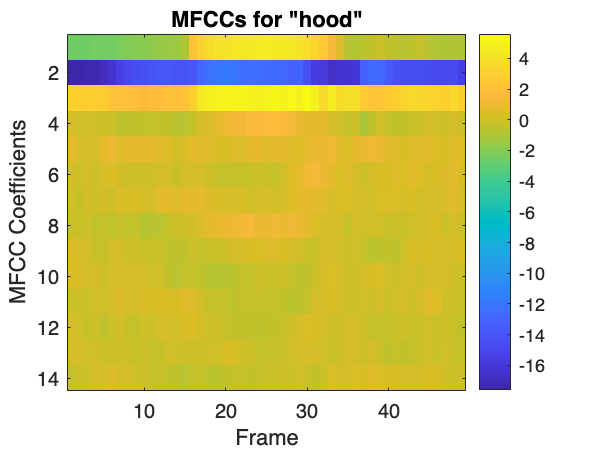


imagesc(mfcc_hood');  
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "hood"');

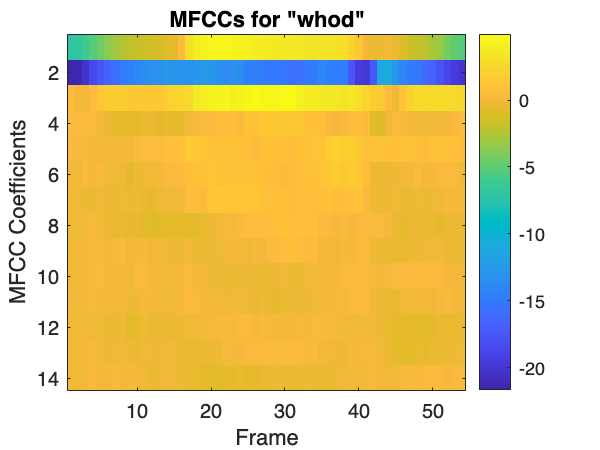


imagesc(mfcc_whod'); 
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "whod"');

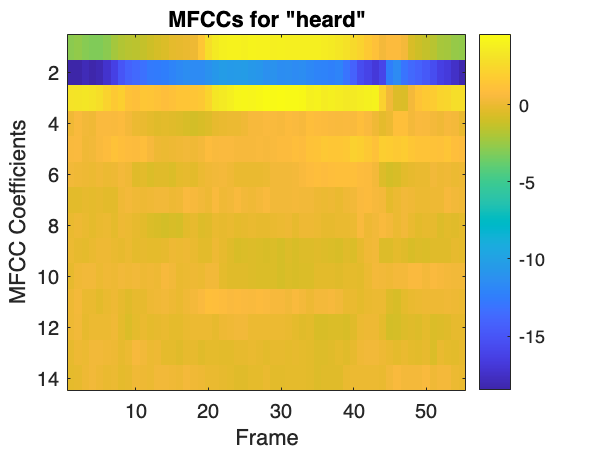


imagesc(mfcc_heard');  
colorbar;
xlabel('Frame');
ylabel('MFCC Coefficients');
title('MFCCs for "heard"');



% PLAY THE AUDIOS WITH THEIR CORRESPONDING SAMPLE RATES
sound(heed, fs_heed);  % Play 'heed'
pause(length(heed)/fs_heed);
sound(hid, fs_hid);  % Play 'hid'
pause(length(hid)/fs_hid); 
sound(head, fs_head); % PLay 'head'
pause(length(head)/fs_head);  
sound(had, fs_had);  % Play 'had'
pause(length(had)/fs_had);
sound(hard, fs_hard);  % Play 'hard'
pause(length(hard)/fs_hard);
sound(hud, fs_hud);  % Play 'hud'
pause(length(hud)/fs_hud);
sound(hod, fs_hod);  % Play 'hod'
pause(length(hod)/fs_hod);
sound(hoard, fs_hoard);  % Play 'hoard'
pause(length(hoard)/fs_hoard);
sound(hood, fs_hood);  % Play 'hood'
pause(length(hood)/fs_hood);
sound(whod, fs_whod);  % Play 'whod'
pause(length(whod)/fs_whod);
sound(heard, fs_heard);  % Play 'heard'
pause(length(heard)/fs_heard);